## Log-likelihood: DC signal in WGN

Compute the log-likelihood function for data $\overline{y}$ that is a realization of White Gaussian Noise (WGN) with a non-zero mean, $\mu_0$, and unit variance.

### Likelihood function

The likelihood function is simply the joint pdf of the data but seen as a function over the parameters of the pdf. For our case, the likelihood function is shown below.

Data: $\overline{y} = (y_0, y_1, y_2,\ldots,y_{N-1})$

Mean: $\mu$


$$L(\mu;\overline{y}) = p_{\overline{Y}}(\overline{y};\mu)=\Pi_{i = 0}^{N-1} \frac{1}{\sqrt{2\pi}} \exp\left(-\frac{1}{2}(y_i -\mu)^2 \right)$$


The log-likelihood function is given by,


$$\ln (L (\mu; \overline{y})) = Const. - \sum_{i = 0}^{N-1}\frac{1}{2}(y_i-\mu)^2$$


where the constant is: $N\left(\ln(1) - \frac{1}{2}\ln(2\pi)\right)$

### Data simulation

We will simulate a data realization by adding a WGN realization to a given value of $\mu_0$ (the true mean).

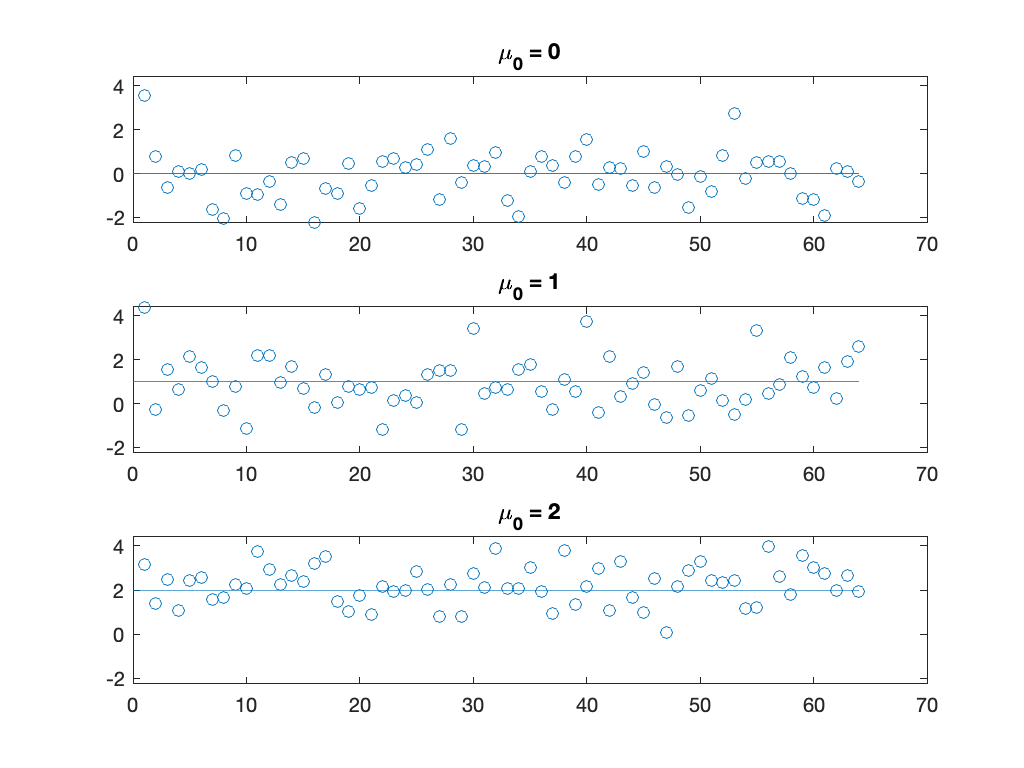

%True mean values to use for simulating the data: we will simulate one data
%realization for each true mean value
muTr = [0;  1;  2];
nRlz = length(muTr);
%Number of samples in realizations
nSamples = 64;
%Generate data realizations
dataMat = randn(nRlz, nSamples)+muTr;
%Plot
figure;
minDat = min(dataMat(:));
maxDat = max(dataMat(:));
for lp = 1:nRlz
    subplot(nRlz,1,lp);
    plot(dataMat(lp,:),'o');
    hold on;
    line([0,nSamples],[muTr(lp),muTr(lp)]);
    title(['\mu_0 = ',num2str(muTr(lp))]);
    ylim([minDat,maxDat]);
end

### Log-likelihood computation

Here, we will pretend that we do not know the true mean $\mu_0$ for a given data realization. We would like to deduce it from the data realization using the log-likelihood function. We will plot the log-likelihood function for different values of the mean and see where we get its maximum value.

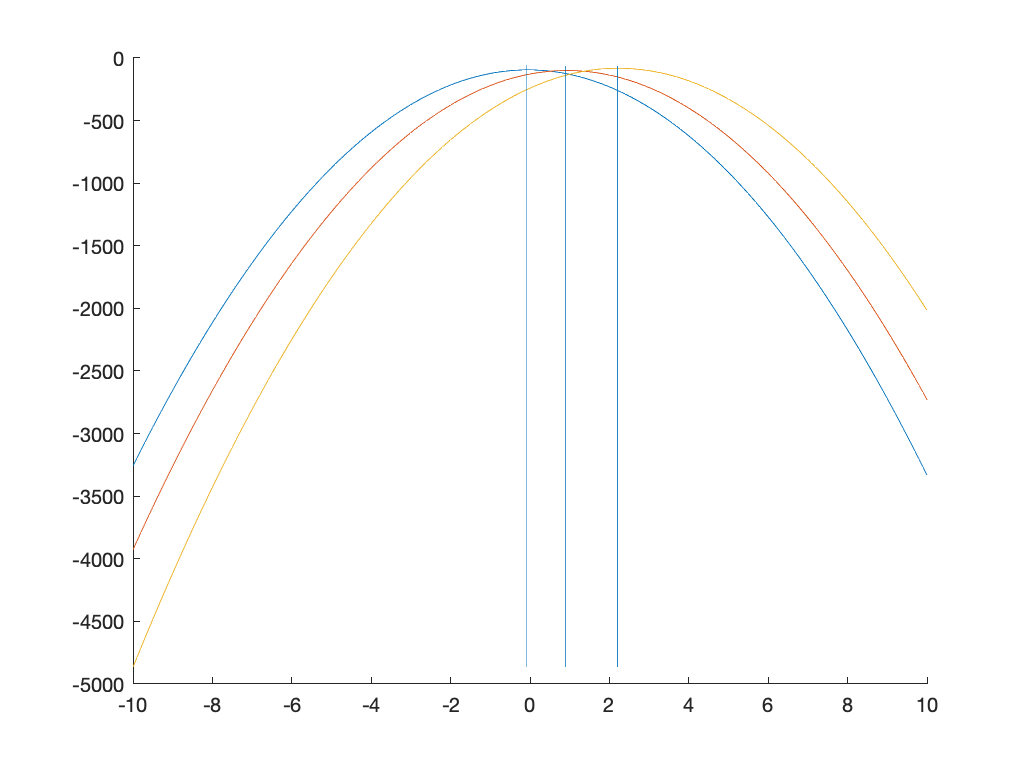

%Vector of mean values for plotting the log-likihood: We will get the
%estimate by looking for the maximum of this curve
muVec4plot = -10:0.1:10;
%Log-likelihood
normConst = nSamples*(log(1)-(1/2)*log(2*pi));
llMat = zeros(nRlz,length(muVec4plot));
%Compute log-likelihood function for each data realization
figure;
hold on;
for lp1 = 1:nRlz
    for lp2 = 1:length(muVec4plot)
        llMat(lp1,lp2) = normConst - (1/2)*sum((dataMat(lp1,:)-muVec4plot(lp2)).^2);
    end
    plot(muVec4plot,llMat(lp1,:));
end
%Plot locations of the maxima
minLL = min(llMat(:));
for lp = 1:nRlz
    %Location of maximum of log-likelihood function
    [maxll,locMaxll] = max(llMat(lp,:));
    line([muVec4plot(locMaxll),muVec4plot(locMaxll)],[minLL,normConst]);
end